# Experiment No 3-

# Bit error rate of Binary Phase Shift Keying (BPSK) in Additive White Gaussian Noise (AWGN)

#### Kushagra Khatwani

190020021

- Matlab Initialization-

close all;
clear;
clc;

- Message Signal-

%msg signal
num = 20000;                            %No of bits in the message
const = exp(1i*2*pi.*[0,1]/2);          %Constellation
msg = randi([0,1],num,1);               %Message

- BPSK Modulation-

%BPSK modulation
BPSK = (msg==0)*(-1)+(msg==1)*(1);  %If bit==1 map to 1 else if bit==0 map to -1

- Demodualtion and Bit Error Rate Calculation-

ebnodb = -10:10;    % SNR array varying in the range of -10 to +10 dB in steps of 1 dB
number_snrs = length(ebnodb);
perr_est = zeros(number_snrs,1);   % Declaring array having all zeroes

%Demodulation
for n=1:number_snrs
    sigma = sqrt(1/(2*(10^(ebnodb(n)/10))));
    w = sigma*randn(num,1)+1i*sigma*randn(num,1);  %Random 2D gaussian noise generation
    r = BPSK+w;           %Received signal
%METHOD 1 for demodulation(using for loop)-
%takes long time using for loop that is why commented this method
    %decisions=zeros(num,1);
    %for k=1:num 
     %   distances = abs(r(k)-const);
     %   [min_dist,decisions(k)] = min(distances); 
     %   demod=(decisions==1)*(1);
    %end
%errors = (demod ~= msg);
%perr_est(n) = sum(errors)/num;
%end

%Method 2 for Demodulation(without using for loops)-
% creating array of  size (num,2) with 
% each row as constellation array
arr1=ones(num,2).*const;
% creating array size (num,2) with 
% each column as received signal array
arr2=[r,r];
% finding distance between 
% constellation points and received signal
% idx stores index(1 or 2) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% using index to get demodulated signal bit array 
% idx=1 is bit=1 and idx=2 is bit=0
demod=(idx==1)*(1);
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
perr_est(n)=sum(demod~=msg)/num;
end

- Plotting-

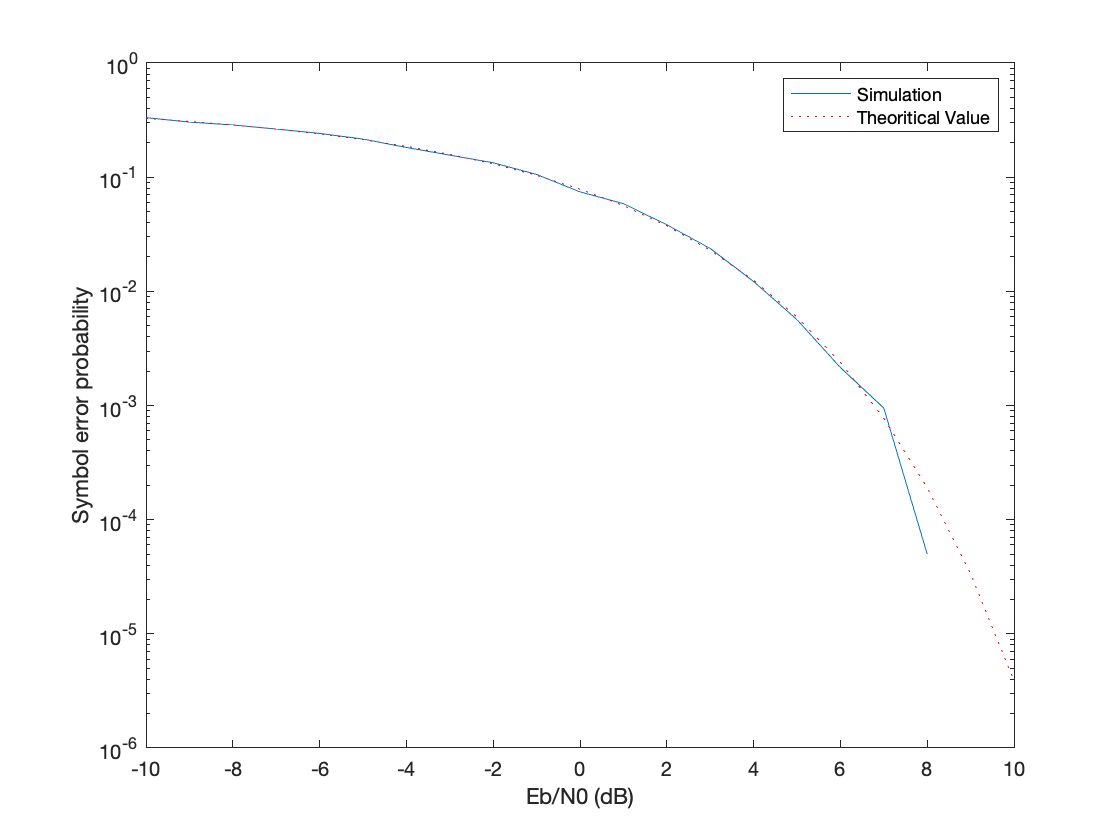

semilogy(ebnodb,perr_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(ebnodb/10); % raw SNR values
perr_th = qfunc(sqrt(2*snro)); % theoretical error
semilogy(ebnodb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;